% Clear workspace and command window
clear all; close all; clc;

%% Parameters for the Non-Dimensional System
lambda = 0.017 / 365;       % Human birth rate (per day)
ds = 0.0079 / 365;          % Human death rate (per day)
beta = 0.015;          % Infection rate by zombies (per day per zombie)
a = 0.01/100;                   % Vampire hunting rate (per day per human)
b = 0.1;                    % Vampire conversion factor
c = 0.0005;                  % Effect of zombies on vampires (per day per zombie)
k_H = 0.002;                % Zombie elimination rate by humans (per day per zombie)
k_V = 0.01;               % Zombie elimination rate by vampires (per day per zombie)
p = 0.0033;                    % Self-regulation parameter for vampires
H0 = 99;                    % Initial human population

%% Calculate Non-Dimensional Parameters
M = a * H0 / (lambda - ds);             % Non-dimensional hunting rate by vampires
Gamma = beta * H0 / (lambda - ds);      % Non-dimensional infection rate by zombies
N = a * b * H0 / (lambda - ds);         % Non-dimensional vampire conversion factor
O = ds / ((lambda - ds) * p);           % Non-dimensional death rate for vampires
C = c * H0 / (lambda - ds);             % Non-dimensional effect of zombies on vampires
K_H = k_H * H0 / (lambda - ds);         % Non-dimensional zombie elimination rate by humans
K_V = k_V * H0 / (lambda - ds);         % Non-dimensional zombie elimination rate by vampires

%% Initial Non-Dimensional Populations
h0 = 1;              % Initial non-dimensional human population
v0 = 99 / H0;         % Initial non-dimensional vampire population
z0 = 1 / H0;          % Initial non-dimensional zombie population
HVZ_initial_ND = [h0; v0; z0];


%% Time Step and Total Simulation Time
deltaT_ND = 0.000001;        % Time step
tTotal_ND = 5;           % Total non-dimensional time



%% Predict Using RK4
t_ND = 0:deltaT_ND:tTotal_ND;
numSteps = length(t_ND);
HVZ_RK_ND = zeros(3, numSteps);
HVZ_RK_ND(:, 1) = HVZ_initial_ND;

for n = 1:numSteps - 1
    HVZ_RK_ND(:, n + 1) = SIR_HVZ_RK4(deltaT_ND, HVZ_RK_ND(:, n), M, Gamma, N, O, C, K_H, K_V, p);
end

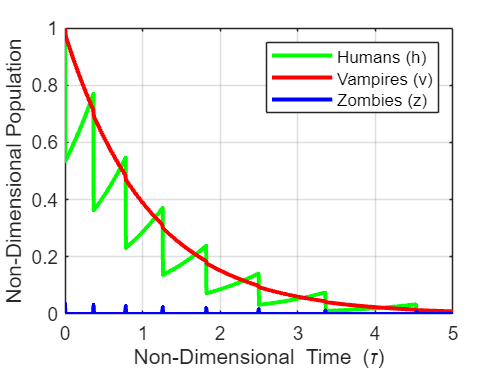


%% Plot Results
figure;
plot(t_ND, HVZ_RK_ND(1, :), 'g-', 'LineWidth', 2); hold on;
plot(t_ND, HVZ_RK_ND(2, :), 'r-', 'LineWidth', 2);
plot(t_ND, HVZ_RK_ND(3, :), 'b-', 'LineWidth', 2);
xlabel('Non-Dimensional Time (\tau)');
ylabel('Non-Dimensional Population');
legend('Humans (h)', 'Vampires (v)', 'Zombies (z)', 'Location', 'northeast');
%title('Non-Dimensional Human-Vampire-Zombie Dynamics');
grid on;
hold off;

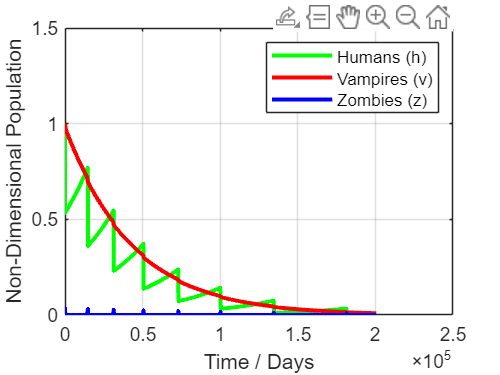

%Plot in days
figure;
plot(t_ND/(lambda-ds), HVZ_RK_ND(1, :), 'g-', 'LineWidth', 2); hold on;
plot(t_ND/(lambda-ds), HVZ_RK_ND(2, :), 'r-', 'LineWidth', 2);
plot(t_ND/(lambda-ds), HVZ_RK_ND(3, :), 'b-', 'LineWidth', 2);
xlabel('Time / Days');
ylabel('Non-Dimensional Population');
legend('Humans (h)', 'Vampires (v)', 'Zombies (z)', 'Location', 'northeast');
%title('Non-Dimensional Human-Vampire-Zombie Dynamics');
ylim([0 1.5])
grid on;
hold off;

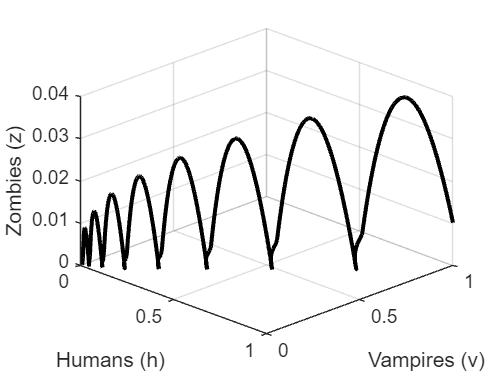


%% Phase Plot: Humans vs Vampires vs Zombies
figure;
plot3(HVZ_RK_ND(1, :), HVZ_RK_ND(2, :), HVZ_RK_ND(3, :), 'k-', 'LineWidth', 2);
xlabel('Humans (h)');
ylabel('Vampires (v)');
zlabel('Zombies (z)');
%title('Phase Plot: Non-Dimensional Humans vs Vampires vs Zombies');
grid on;
view(45, 30); % Adjust the view angle
hold on 
scatter(0,0,0.0002,'r','filled')

%%Solve for equilibrium points (V>=p*H)
equilibrium_eqns = @(x) [
    1 - Gamma * x(3);                        % dh/dτ = 0 -> 1 - Gamma * z = 0
    -O * p - C * x(3);                       % dv/dτ = 0 -> -O * p - C * z = 0
    Gamma * x(1) - K_H * x(1) - K_V * x(2);  % dz/dτ = 0 -> Gamma * h - K_H * h - K_V * v = 0
];

%% Initial Guess for Equilibrium Points
initial_guess = [1; 0.01; 0.01];

%% Solve the System of Equations
options = optimoptions('fsolve', 'Display', 'iter');
[equilibrium, fval, exitflag] = fsolve(equilibrium_eqns, initial_guess, options);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          4         2.62429e+09                        2.64e+09              1
     1          8              9364.2       0.786586         5.77e+06              1
     2         12             0.84513     0.00162365         9.43e+03           1.97
     3         16            0.811738    2.80584e-06             20.6           1.97
     4         20            0.811738    5.79032e-09           0.0336           1.97
     5         24            0.811738    1.00068e-11         7.33e-05           1.97

No solution found.

fsolve stopped because the last step was ineffective. However, the vector of function
values is not near zero, as measured by the value of the <


%% Display the Results
if exitflag > 0
    fprintf('Equilibrium Point Found:\n');
    fprintf('h = %.4f\n', equilibrium(1));
    fprintf('v = %.4f\n', equilibrium(2));
    fprintf('z = %.4f\n', equilibrium(3));
else
    disp('No equilibrium point found.');
end

No equilibrium point found.


%%Solve for equilibrium points (V>p*H)
equilibrium_eqns = @(x) [
    x(1) * (1 - M * x(2) * (1 - x(2) / (p * x(1))) - Gamma * x(3));                    % dh/dτ = 0
    x(2) * (N * x(1) * (1 - x(2) / (p * x(1))) - O * x(2) - C * x(3));                 % dv/dτ = 0
    x(3) * (Gamma * x(1) - K_H * x(1) - K_V * x(2))                                    % dz/dτ = 0
];

%% Initial Guess for Equilibrium Points
initial_guess = [1; 0.01; 0.01];

%% Solve the System of Equations
options = optimoptions('fsolve', 'Display', 'iter');
[equilibrium, fval, exitflag] = fsolve(equilibrium_eqns, initial_guess, options);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          4              606458                        6.12e+07              1
     1          8             35606.5       0.587263         6.12e+06              1
     2         12             1988.78       0.254375         5.54e+05           1.47
     3         16             105.113       0.101541         4.57e+04           1.47
     4         20             5.27485      0.0375643         3.47e+03           1.47
     5         24            0.252292      0.0130774              246           1.47
     6         28           0.0114582     0.00434697             16.1           1.47
     7         32         0.000484624     0.00139446            0.962           1.47
     8         36         1.81081e-05    0.000438876            0.125           1.47
     9         40         5.20219e-07    0.000143074           0


%% Display the Results
if exitflag > 0
    fprintf('Equilibrium Point Found:\n');
    fprintf('h = %.4f\n', equilibrium(1));
    fprintf('v = %.4f\n', equilibrium(2));
    fprintf('z = %.4f\n', equilibrium(3));
else
    disp('No equilibrium point found.');
end

Equilibrium Point Found:


h = 0.0000


v = 0.0000


z = 0.0002
